# Multivariant regression

**Author: CARLOS M N**

**DNI: XXXXXXXX-X**

Clear workspace

clear all; clc; close all;

## Initialize variables

**x1**: 1000 uniformly distributed points between 0 and 10

x1 = 10*rand(1000, 1);
min(x1)

ans = 0.0211

max(x1)

ans = 9.9951

**x2**: 1000 uniformly distributed points between 10 and 20

x2 = 10+10*rand(1000, 1);
min(x2)

ans = 10.0037

max(x2)

ans = 19.9906

**x3**: 1000 uniformly distributed points between 5 and 10

x3 = 5+5*rand(1000, 1);
min(x3)

ans = 5.0062

max(x3)

ans = 9.9999

**eps**: random error --> normal distribution ( /mu=0, /sigma=1) = Standard normal distrib

eps = randn(1000, 1);
std(eps)

ans = 1.0265

**y**: variable to be reconstructed

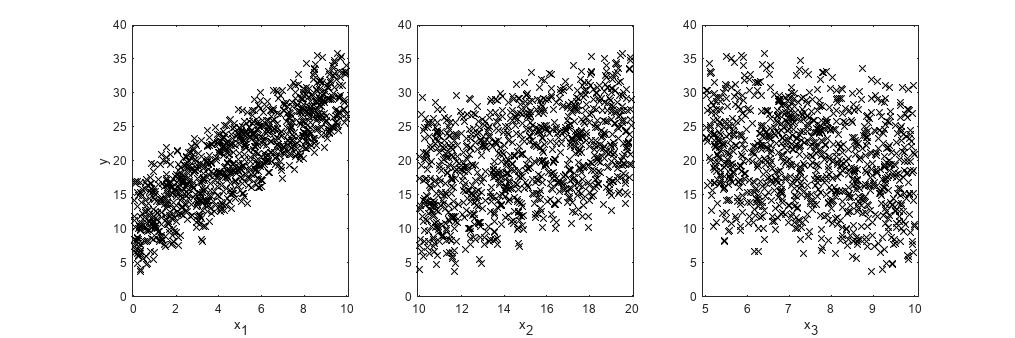

y = 3 + 2*x1 + x2 - x3 + eps;

figure(100)
ax1 = subplot(1,3,1);
plot(x1,y,'xk')
xlabel('x_1')
ylabel('y')
xlim([min(x1)-0.1, max(x1)+0.1])

ax2 = subplot(1,3,2);
plot(x2,y,'xk')
xlabel('x_2')
xlim([min(x2)-0.1, max(x2)+0.1])

ax3 = subplot(1,3,3);
plot(x3,y,'xk')
xlabel('x_3')
xlim([min(x3)-0.1, max(x3)+0.1])

linkaxes([ax1, ax2, ax3], 'y');
width=1200;
height=400;
set(gcf,'position',[0,0,width,height])

## Lineal adjust regression

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.6349
    2.0099
    1.0068
   -0.9667



disp(bint)

    2.1404    3.1293
    1.9874    2.0325
    0.9851    1.0285
   -1.0116   -0.9218



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.97558


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:13263.8898   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):1.0535


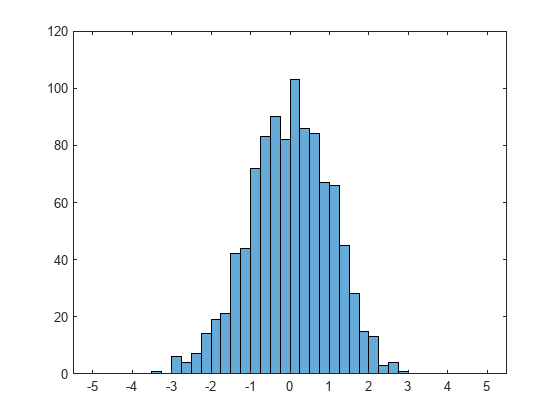


figure(1)
histogram(r,[-5:0.25:5])

## Modify variability of error

edges = [-5:0.25:5];

### sigma = 0 --> no error

y = 3 + 2*x1 + x2 - x3;

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.0000
    2.0000
    1.0000
   -1.0000



disp(bint)

    3.0000    3.0000
    2.0000    2.0000
    1.0000    1.0000
   -1.0000   -1.0000



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:1


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:2.897369022825098e+32   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):4.7908e-29


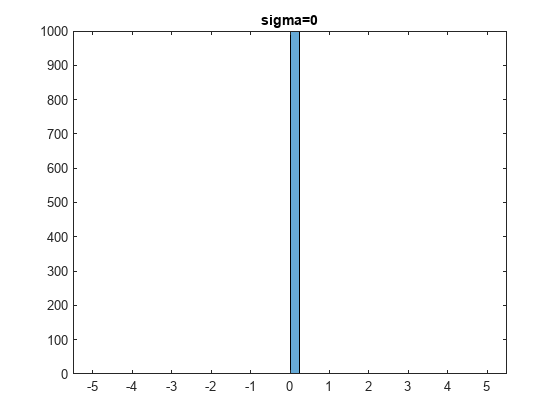


figure(2)
histogram(r,edges)
title('sigma=0')
% saveas(gcf,'03_Multivar/hist_sigma_0.png')

### sigma = 0.1

y = 3 + 2*x1 + x2 - x3 + 0.1*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.0216
    1.9984
    1.0007
   -1.0032



disp(bint)

    2.9739    3.0693
    1.9962    2.0006
    0.9986    1.0028
   -1.0076   -0.9989



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.99977


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:1414497.7643   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):0.0098075


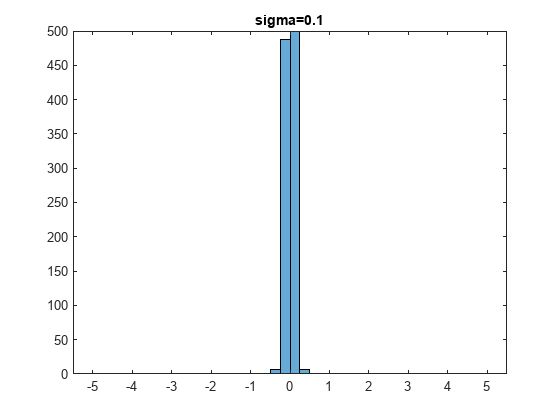


figure(3)
histogram(r,edges)
title('sigma=0.1')
% saveas(gcf,'03_Multivar/hist_sigma_01.png')

### sigma = 0.5

y = 3 + 2*x1 + x2 - x3 + 0.5*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.8621
    2.0039
    1.0006
   -0.9845



disp(bint)

    2.6156    3.1086
    1.9927    2.0152
    0.9898    1.0114
   -1.0069   -0.9621



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.99379


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:53109.0524   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):0.26177


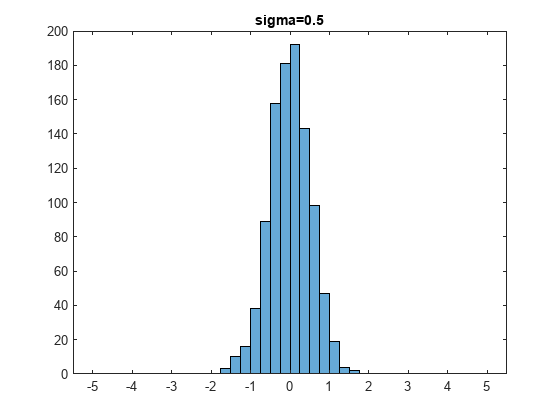


figure(4)
histogram(r,edges)
title('sigma=0.5')
% saveas(gcf,'03_Multivar/hist_sigma_05.png')

### sigma = 1

y = 3 + 2*x1 + x2 - x3 + 1*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    3.1897
    1.9970
    0.9864
   -0.9916



disp(bint)

    2.7129    3.6666
    1.9752    2.0187
    0.9655    1.0074
   -1.0349   -0.9484



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.97691


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:14047.8203   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):0.97976


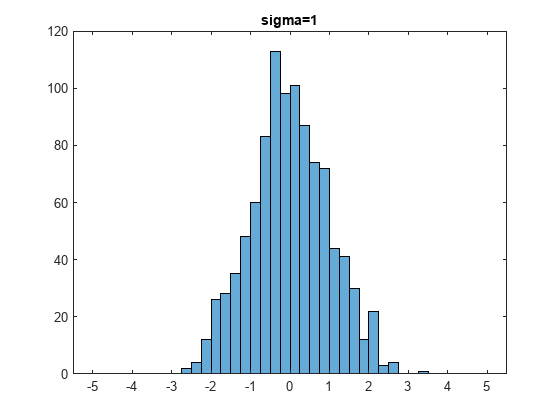


figure(5)
histogram(r,edges)
title('sigma=1')
% saveas(gcf,'03_Multivar/hist_sigma_1.png')

### sigma = 2

y = 3 + 2*x1 + x2 - x3 + 2*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.4687
    2.0333
    1.0131
   -0.9650



disp(bint)

    1.5491    3.3883
    1.9913    2.0752
    0.9728    1.0535
   -1.0485   -0.8816



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.92176


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:3911.1179   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):3.6438


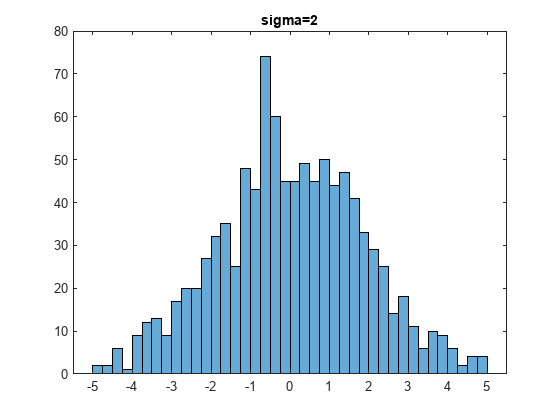


figure(6)
histogram(r,edges)
title('sigma=2')
% saveas(gcf,'03_Multivar/hist_sigma_2.png')

### sigma = 5

edges = [-100:5:100];

y = 3 + 2*x1 + x2 - x3 + 5*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    4.1274
    1.9144
    0.9888
   -1.0575



disp(bint)

    1.6878    6.5670
    1.8030    2.0258
    0.8818    1.0959
   -1.2789   -0.8361



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.60489


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:508.2713   ==>   p(>F):2.8732e-200


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):25.6447


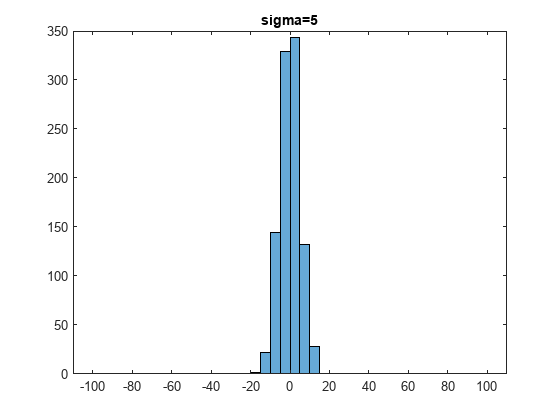


figure(7)
histogram(r,edges)
title('sigma=5')
% saveas(gcf,'03_Multivar/hist_sigma_5.png')

### sigma = 10

y = 3 + 2*x1 + x2 - x3 + 10*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.5839
    2.1259
    1.0211
   -1.1077



disp(bint)

   -2.1859    7.3536
    1.9082    2.3436
    0.8118    1.2304
   -1.5406   -0.6749



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.32286


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:158.2938   ==>   p(>F):6.8592e-84


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):98.028


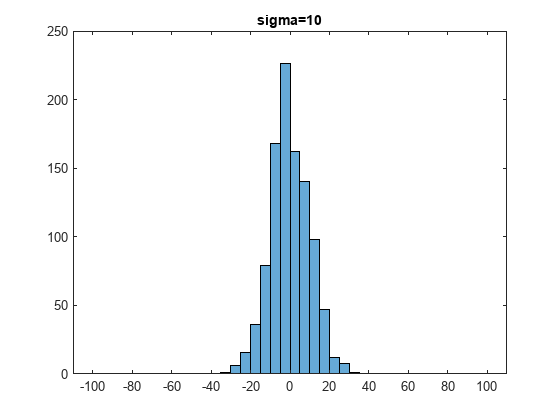


figure(8)
histogram(r,edges)
title('sigma=10')
% saveas(gcf,'03_Multivar/hist_sigma_10.png')

### sigma = 20

y = 3 + 2*x1 + x2 - x3 + 20*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.1545
    1.7714
    0.9000
   -0.6181



disp(bint)

   -7.3299   11.6389
    1.3385    2.2044
    0.4839    1.3162
   -1.4788    0.2426



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.076485


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:27.496   ==>   p(>F):4.3599e-17


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):387.5961


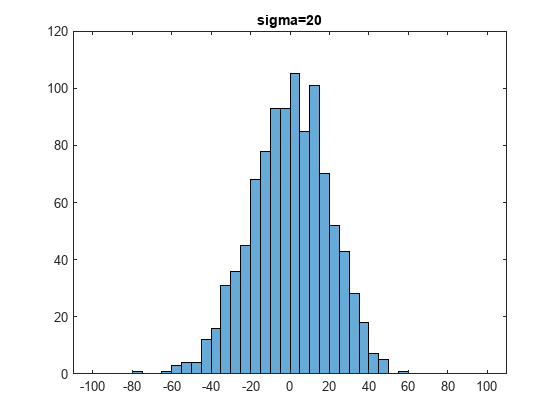


figure(9)
histogram(r,edges)
title('sigma=20')
% saveas(gcf,'03_Multivar/hist_sigma_20.png')

### sigma = 50

y = 3 + 2*x1 + x2 - x3 + 50*randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

   21.1056
    2.0735
    0.1449
   -1.8854



disp(bint)

   -2.7092   44.9204
    0.9864    3.1606
   -0.9000    1.1898
   -4.0465    0.2757



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.016808


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:5.6755   ==>   p(>F):0.00074414


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):2443.7441


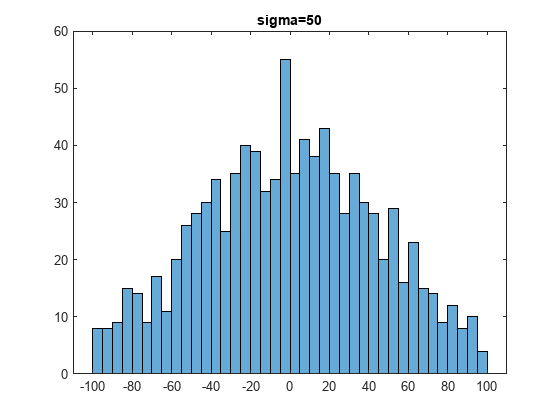


figure(10)
histogram(r,edges)
title('sigma=50')
% saveas(gcf,'03_Multivar/hist_sigma_50.png')

## Residual analysis for sigma=1

y = 3 + 2*x1 + x2 - x3 + randn(1000,1);

X = [ones(size(x1,1),1) x1 x2 x3];
[b, bint, r, rint, stats] = regress(y,X);
disp(b)

    2.9708
    1.9966
    0.9935
   -0.9800



disp(bint)

    2.4748    3.4668
    1.9740    2.0193
    0.9717    1.0152
   -1.0250   -0.9350



disp(strcat('r^2:  ',num2str(stats(1))))

r^2:0.9751


disp(strcat('F-stat:  ',num2str(stats(2)),'   ==>   p(>F):  ',num2str(stats(3))))

F-stat:13001.0876   ==>   p(>F):0


disp(strcat('var(err):  ',num2str(stats(4))))

var(err):1.06


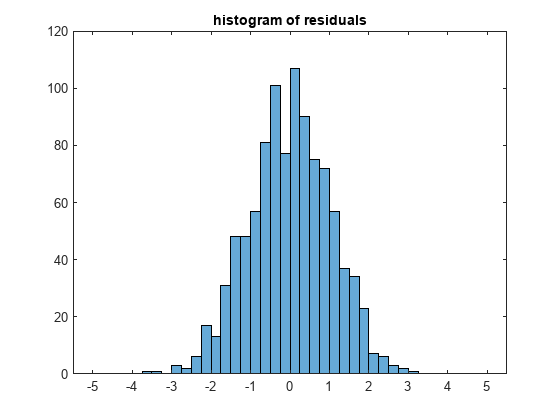

figure(11)
histogram(r,[-5:0.25:5])
title('histogram of residuals')
% saveas(gcf,'03_Multivar/histr_multivar.png')

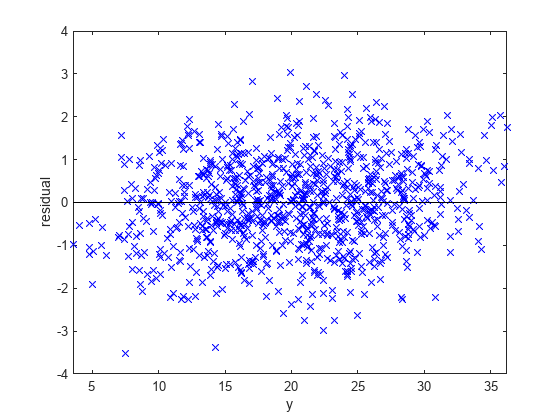

figure(12)
plot(y,r,'xb')
hold on
plot([min(y) max(y)], [0 0], 'k')
xlim([min(y) max(y)])
xlabel('y')
ylabel('residual')
hold off
% saveas(gcf,'03_Multivar/residuals_multivar.png')

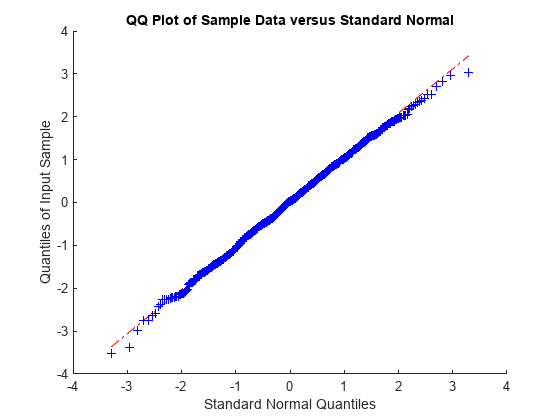

figure(13)
qqplot(r)
% saveas(gcf,'03_Multivar/qq_multivar.png')

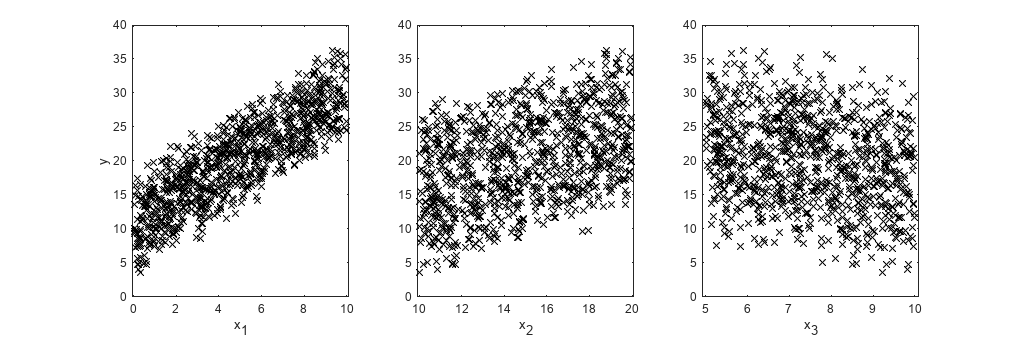



figure(101)
ax1 = subplot(1,3,1);
plot(x1,y,'xk')
xlabel('x_1')
ylabel('y')
xlim([min(x1)-0.1, max(x1)+0.1])

ax2 = subplot(1,3,2);
plot(x2,y,'xk')
xlabel('x_2')
xlim([min(x2)-0.1, max(x2)+0.1])

ax3 = subplot(1,3,3);
plot(x3,y,'xk')
xlabel('x_3')
xlim([min(x3)-0.1, max(x3)+0.1])

linkaxes([ax1, ax2, ax3], 'y');
width=1200;
height=400;
set(gcf,'position',[0,0,width,height])
% saveas(gcf,'03_Multivar/multivar_data.png')

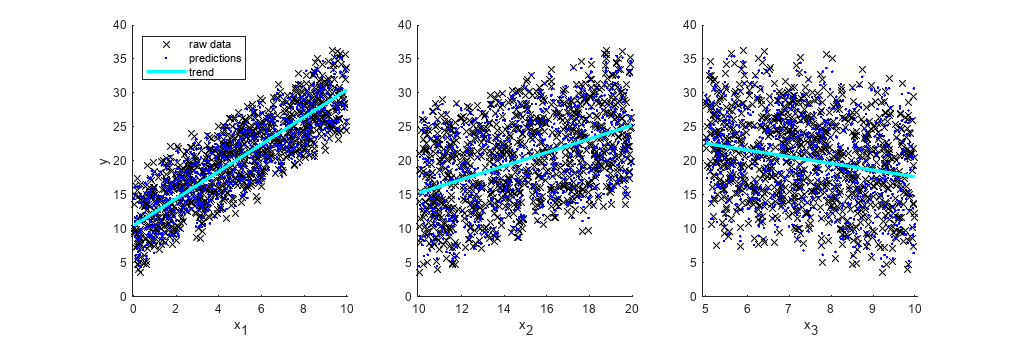

y_adj = X*b;

figure(102)
ax1 = subplot(1,3,1);
hold on
plot(x1,y,'xk')
plot(x1,y_adj,'b.')
plot([min(x1); max(x1)], [b(1)+b(2)*min(x1)+b(3)*mean(x2)+b(4)*mean(x3); ...
                          b(1)+b(2)*max(x1)+b(3)*mean(x2)+b(4)*mean(x3)],'c', LineWidth=2.5)
hold off
xlabel('x_1')
ylabel('y')
legend('raw data', 'predictions', 'trend', Location='northwest')
xlim([min(x1)-0.1, max(x1)+0.1])

ax2 = subplot(1,3,2);
hold on
plot(x2,y,'xk')
plot(x2,y_adj,'b.')
plot([min(x2); max(x2)], [b(1)+b(3)*min(x2)+b(2)*mean(x1)+b(4)*mean(x3); ...
                          b(1)+b(3)*max(x2)+b(2)*mean(x1)+b(4)*mean(x3)],'c', LineWidth=2.5)
hold off
xlabel('x_2')
xlim([min(x2)-0.1, max(x2)+0.1])

ax3 = subplot(1,3,3);
hold on
plot(x3,y,'xk')
plot(x3,y_adj,'b.')
plot([min(x3); max(x3)], [b(1)+b(4)*min(x3)+b(2)*mean(x1)+b(3)*mean(x2); ...
                          b(1)+b(4)*max(x3)+b(2)*mean(x1)+b(3)*mean(x2)],'c', LineWidth=2.5)
hold off
xlabel('x_3')
xlim([min(x3)-0.1, max(x3)+0.1])

linkaxes([ax1, ax2, ax3], 'y');
width=1200;
height=400;
set(gcf,'position',[0,0,width,height])
% saveas(gcf,'03_Multivar/multivar_adjust.png')